# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file='rorc_model.xlsx';
data=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [TCND30] are valid
INFO: cStatusLogger. Exergy values [TCND45] are valid
INFO: cStatusLogger. Exergy values [ETAT75] are valid
INFO: cStatusLogger. Exergy values [PBLR15] are valid
INFO: cStatusLogger. Exergy values [NoIHE] are valid
INFO: cStatusLogger. Exergy values [N_Butane] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model rorc_model.xlsx is valid


#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
DiagnosisMethod='WASTE_OUTPUT';

#### Compute Cost Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod);

#### Show Results

res.fuelImpact;

Fuel Impact:    5.7300 (kW)


printResults(res);

Diagnosis Summary

 Key      MF(kW)     DI(kW)    DPs(kW)    MF*(kW)    MR*(kW)   DPs*(kW)
------------------------------------------------------------------------
 BLR     -0.3935     0.8960     0.0000    -0.3935     0.0000     0.0000
 TRB      3.9139     3.9640     0.0000     5.1755     0.0000     0.0000
 IHE      0.0309     0.1590     0.0000     0.0431     0.0000     0.0000
 PMP     -0.0012     0.0230     0.0000    -0.0019     0.0000     0.0000
 CND      0.0000     0.0000     0.6880     0.0138     0.0000     0.8930
 ENV      3.5501     5.0420     0.6880     4.8370     0.0000     0.8930


Malfunction Table (kW)

              BLR       TRB       IHE       PMP       CND       DPs
--------------------------------------------------------------------
 BLR       0.0000    3.5484    0.0239    0.0000   -0.0252    0.0000
 TRB       0.0000    0.0000    0.0000   -0.0012    0.0000    0.0000
 IHE       0.0000    0.2597    0.0061    0.0000    0.0251    0.0000
 PMP       0.0000    0.1057    0.0008

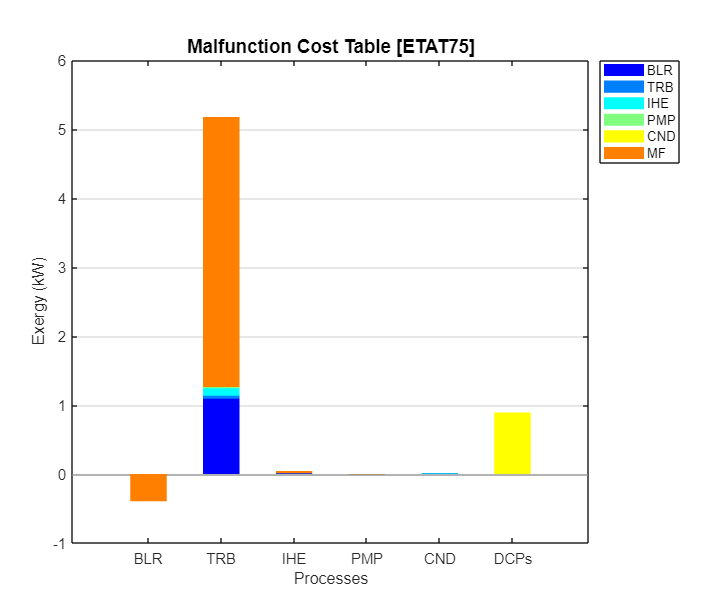

graphDiagnosis(res);